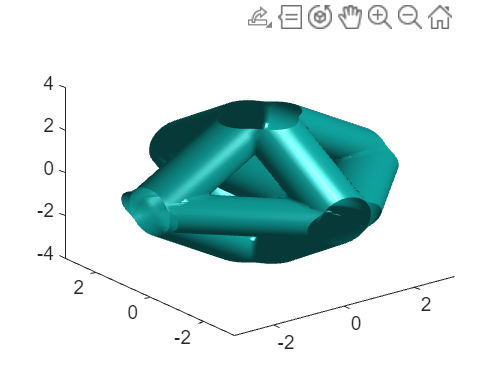

clc;clear;



FaiPartc_com = 0;
% 数据集的可变参数
tPart = 1.5;


X = linspace(-pi,pi,50);
Y = linspace(-pi,pi,50);
Z = linspace(-pi,pi,50);
[x,y,z] = meshgrid(X,Y,Z);

endpoint = [0 0 pi 0 -pi 0
    0 0 pi pi 0 0
    0 0 pi 0 pi 0
    0 0 pi -pi 0 0
    0 0 -pi 0 -pi 0
    0 0 -pi pi 0 0
    0 0 -pi 0 pi 0
    0 0 -pi -pi 0 0
    
    
    
    
    
    
    
    
    
    
    ];


i=1;
for i =1:size(endpoint,1)
FaiPartc_com = StrutGen(endpoint(i,:),tPart,FaiPartc_com);
end

figure(5001)
isosurface(x,y,z,FaiPartc_com,0)





% 每个圆柱的端面坐标
x1=-pi;y1=-pi;z1=-pi;
x2=pi;y2=pi;z2=pi;

x0=(x1+x2)/2;y0=(y1+y2)/2;z0=(z1+z2)/2;LPart=sqrt((x2-x1).^2+(y2-y1).^2+(z2-z1).^2);
dx2=x2-x0;dy2=y2-y0;dz2=z2-z0;
dx=x-x0;dy=y-y0;dz=z-z0;
Ld = sqrt(dx.^2+dy.^2+dz.^2);
cos_ThetaPart = sqrt(((dx*dx2+dy*dy2+dz*dz2)./(Ld*sqrt(dx2^2+dy2^2+dz2^2))).^2);
sin_ThetaPart = sqrt(1-cos_ThetaPart.^2);

FaiPartc1 =  (LPart/2)^2-(cos_ThetaPart.*Ld).^2;
FaiPartc2 =  (tPart/2).^2-(sin_ThetaPart.*Ld).^2;


FaiPartc_l1 = FaiPartc2;
%% 

% tPart=3;
x1=pi;y1=-pi;z1=-pi;
x2=-pi;y2=pi;z2=pi;

x0=(x1+x2)/2;y0=(y1+y2)/2;z0=(z1+z2)/2;LPart=sqrt((x2-x1).^2+(y2-y1).^2+(z2-z1).^2);
dx2=x2-x0;dy2=y2-y0;dz2=z2-z0;
dx=x-x0;dy=y-y0;dz=z-z0;
Ld = sqrt(dx.^2+dy.^2+dz.^2);
cos_ThetaPart = sqrt(((dx*dx2+dy*dy2+dz*dz2)./(Ld*sqrt(dx2^2+dy2^2+dz2^2))).^2);
sin_ThetaPart = sqrt(1-cos_ThetaPart.^2);

FaiPartc1 =  (LPart/2)^2-(cos_ThetaPart.*Ld).^2;
FaiPartc2 =  (tPart/2).^2-(sin_ThetaPart.*Ld).^2;

FaiPartc_l2 = FaiPartc2;
%% 

% tPart=3;
x1=pi;y1=pi;z1=-pi;
x2=-pi;y2=-pi;z2=pi;

x0=(x1+x2)/2;y0=(y1+y2)/2;z0=(z1+z2)/2;LPart=sqrt((x2-x1).^2+(y2-y1).^2+(z2-z1).^2);
dx2=x2-x0;dy2=y2-y0;dz2=z2-z0;
dx=x-x0;dy=y-y0;dz=z-z0;
Ld = sqrt(dx.^2+dy.^2+dz.^2);
cos_ThetaPart = sqrt(((dx*dx2+dy*dy2+dz*dz2)./(Ld*sqrt(dx2^2+dy2^2+dz2^2))).^2);
sin_ThetaPart = sqrt(1-cos_ThetaPart.^2);

FaiPartc1 =  (LPart/2)^2-(cos_ThetaPart.*Ld).^2;
FaiPartc2 =  (tPart/2).^2-(sin_ThetaPart.*Ld).^2;

FaiPartc_l3 = FaiPartc2;

%% 

% tPart=3;
x1=-pi;y1=pi;z1=-pi;
x2=pi;y2=-pi;z2=pi;

x0=(x1+x2)/2;y0=(y1+y2)/2;z0=(z1+z2)/2;LPart=sqrt((x2-x1).^2+(y2-y1).^2+(z2-z1).^2);
dx2=x2-x0;dy2=y2-y0;dz2=z2-z0;
dx=x-x0;dy=y-y0;dz=z-z0;
Ld = sqrt(dx.^2+dy.^2+dz.^2);
cos_ThetaPart = sqrt(((dx*dx2+dy*dy2+dz*dz2)./(Ld*sqrt(dx2^2+dy2^2+dz2^2))).^2);
sin_ThetaPart = sqrt(1-cos_ThetaPart.^2);

FaiPartc1 =  (LPart/2)^2-(cos_ThetaPart.*Ld).^2;
FaiPartc2 =  (tPart/2).^2-(sin_ThetaPart.*Ld).^2;

FaiPartc_l4 = FaiPartc2;


FaiPartc_com = max(FaiPartc_l1,FaiPartc_l2);
FaiPartc_com = max(FaiPartc_l3,FaiPartc_com);
FaiPartc_com = max(FaiPartc_l4,FaiPartc_com);
% isosurface(x,y,z,FaiPartc_com,0)

figure(5001)
isosurface(x,y,z,FaiPartc_com,0)
isocaps(x,y,z,FaiPartc_com,0)


% 支柱水平集矩阵生成函数

function FaiPartc_com = StrutGen(endpoint,tPart,FaiPartc_com)

X = linspace(-pi,pi,50);
Y = linspace(-pi,pi,50);
Z = linspace(-pi,pi,50);
[x,y,z] = meshgrid(X,Y,Z);

x1=endpoint(1);y1=endpoint(2);z1=endpoint(3);
x2=endpoint(4);y2=endpoint(5);z2=endpoint(6);

x0=(x1+x2)/2;y0=(y1+y2)/2;z0=(z1+z2)/2;LPart=sqrt((x2-x1).^2+(y2-y1).^2+(z2-z1).^2);
dx2=x2-x0;dy2=y2-y0;dz2=z2-z0;
dx=x-x0;dy=y-y0;dz=z-z0;
Ld = sqrt(dx.^2+dy.^2+dz.^2);
cos_ThetaPart = sqrt(((dx*dx2+dy*dy2+dz*dz2)./(Ld*sqrt(dx2^2+dy2^2+dz2^2))).^2);
sin_ThetaPart = sqrt(1-cos_ThetaPart.^2);

FaiPartc1 =  (LPart/2)^2-(cos_ThetaPart.*Ld).^2;
FaiPartc2 =  (tPart/2).^2-(sin_ThetaPart.*Ld).^2;


FaiPartc_l1 = FaiPartc2;

if FaiPartc_com == 0
    FaiPartc_com = FaiPartc_l1;
else
    FaiPartc_com = max(FaiPartc_l1,FaiPartc_com);
end


end